# 1D optimisation of droplet center

#### To generate optimisation procedure for the *(center of the)* initial droplet location

- Select variables for droplet and chose Target Shape

- Plot initial droplet shape based on chosen `x0`

- Use optimisation prosidure to find bes possition of droplet

**Looping erro**

- Set grid size to small value:` xMax = 10`

- If  |`x - x0`|` ~= x0`,   where   `x ≠ x0`

- Then `x_sol = x0 ~≠ x`

**Solution**

- make` xMax >> |x - x0|`

**Gradient distribution erro**

- If `|x - x0| `is too large,` TolX `is met 

- but` |x - x0| `is not close to zero

**Solution**

- Modifi ` costEvaluation...`

- Possibly to account for central difference

**or**

- Just have` x0 `sufficiently close to` x`

- `x0 `should be within targetshape rejion

clear; clc;

## **1) **

**Set some values**

y0 = .1084434390; % Raise droplet profile...
N = 120; % # sample points
A = 17; % Magnitude/Amplitude of droplet
% c1 = 0.0010;  
% c2 = 0.0196;
c1 = 0.0010;  
c2 = 0.0196;

c3 = 0.0013;
c4 = 0.0108;

tfinal = 10^5; % final time >> 1
xMax = 20; 
dx = 2*xMax/(N-1); % Stepsize
X = -xMax:dx:xMax; % Linespace/Mesh
k = 1/(2*xMax/N); %omega
% Possition / Shift
x0 = 5;
x1 = 7.5;
xO0 = 5;
aa=-5;
bb=5;
cc=1;



**Target Shape **`h_target`

a=round(aa/dx+N/2);
b=round(bb/dx+N/2);
c=cc*ones(size(X));

% h_region = ones(size(X));
% h_region(1:(a+b)/2) = c(1:(a+b)/2) + tanh(X(1:(a+b)/2)+bb);
% h_region((a+b)/2+1:end) = c((a+b)/2+1:end) - tanh(X((a+b)/2+1:end)+aa);
% h_region(1:a)=c(1:a);
% h_region(b:end)=c(b:end);
h_region = c;

target = [a,b,h_region];

## **2) **

**Solutions**

Inside

% [tSpan,D1,D2,X,H0,myObjective,conds_Sol,...
%     fval,exitflag,output,history,History,h_Sol,H_Sol]...
%     = SolutionRegion(tfinal,dx,X,k,y0,N,A,c1,c2,x0,target);

[~,~,~,~,H0_Possition,myObjective_Possition,conds_Sol_Possition,...
    ~,~,output_Possition,history_Possition,History_Possition,h_Sol_Possition,H_Sol_Possition]...
    = SolutionPossition(tfinal,dx,X,k,y0,N,A,c1,c2,x0,target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          32.7823         
     1            4          31.6899         initial simplex
     2            6          24.1529         expand
     3            7          24.1529         reflect
     4            9          21.7115         expand
     5           11          13.3297         expand
     6           13           7.5002         expand
     7           15          2.78585         expand
     8           16          2.78585         reflect
     9           17          2.78585         reflect
    10           18          2.78585         reflect
    11           19          2.78585         reflect
    12           21          1.55914         reflect
    13           22          1.55914         reflect
    14           24          1.55914         contract inside
    15           26          1.19485         contract outside
    16           28         0.452351         expand
    17           30         0.


[~,~,~,~,H0_Disjoining,myObjective_Disjoining,conds_Sol_Disjoining,...
    ~,~,output_Disjoining,history_Disjoining,History_Disjoining,h_Sol_Disjoining,H_Sol_Disjoining]...
    = SolutionDisjoining(tfinal,dx,X,k,y0,N,A,c1,c2,history_Possition(end),target);

% [~,~,~,~,H_1,~,conds_Sol_1,...
%     ~,~,output_1,history_1,History_1,h_Sol_1,H_Sol_1]...
%     = SolutionRegion(tfinal,dx,X,k,y0,N,A,c1,c2,x1,target);

[~,~,~,~,H_1Possition,~,conds_Sol_1Possition,...
    ~,~,output_1Possition,history_1Possition,History_1Possition,h_Sol_1Possition,H_Sol_1Possition]...
    = SolutionPossition(tfinal,dx,X,k,y0,N,A,c3,c4,x1,target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          57.9827         
     1            4          57.3057         initial simplex
     2            6          53.7422         expand
     3            8          46.9025         expand
     4           10          42.0011         expand
     5           12          30.8994         expand
     6           14          19.3631         expand
     7           16          3.57597         expand
     8           17          3.57597         reflect
     9           19          3.57597         expand
    10           20          3.57597         reflect
    11           21          3.57597         reflect
    12           26          3.57597         shrink
    13           27          3.57597         reflect
    14           28          3.57597         reflect
    15           30          3.57597         reflect
    16           32          3.57597         contract inside
    17           34          3.57597     


[~,~,~,~,H_1Disjoining,myObjective_1Disjoining,conds_Sol_1Disjoining,...
    ~,~,output_1Disjoining,history_1Disjoining,History_1Disjoining,h_Sol_1Disjoining,H_Sol_1Disjoining]...
    = SolutionDisjoining(tfinal,dx,X,k,y0,N,A,c3,c4,history_Possition(end),target);

var = [A;N;k;y0]; 

h = hFinalRegion(history(:,6)',X,var,D1,D2,tSpan);
H = deval(h,tfinal); 

h1 = hFinalRegion(history_1(:,6),X,var,D1,D2,tSpan);
H1 = deval(h1,tfinal);   

**Inside Figures**

Fig. 0

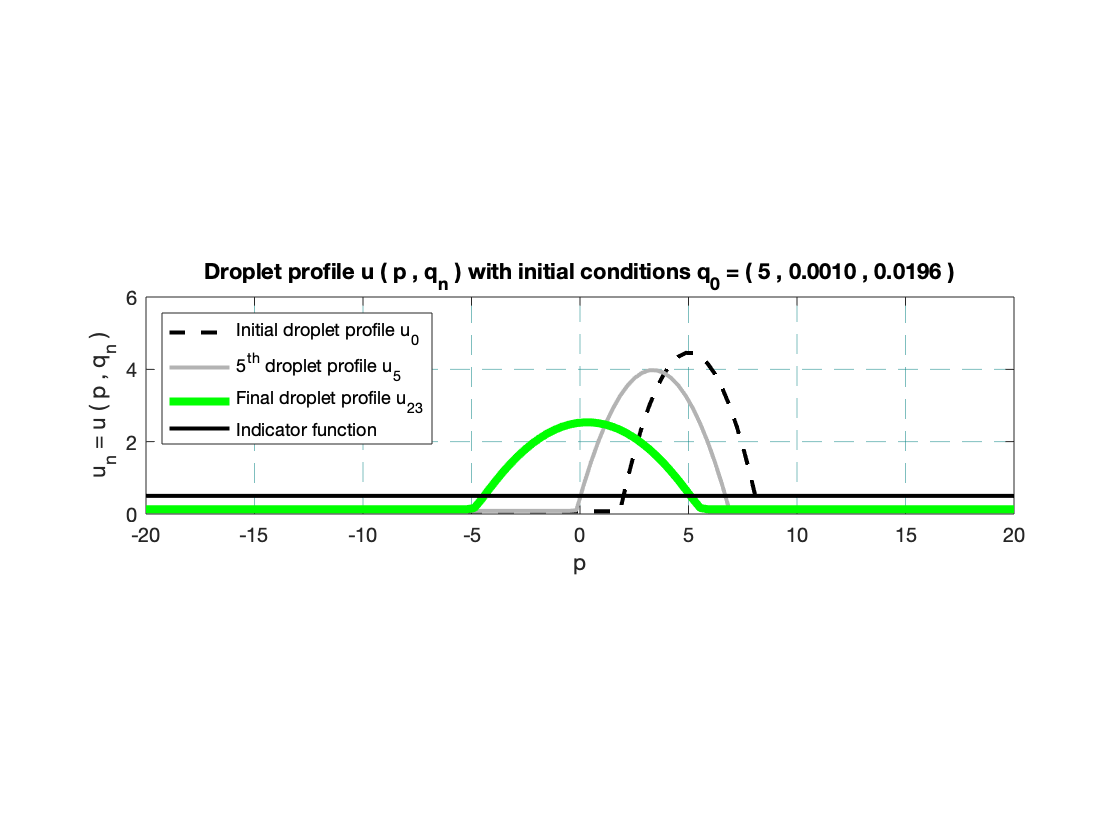

figure;
hold on
plot(X,H0,'k--','linewidth',2);
plot(X,H,'-','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_Sol,'g-','linewidth',4);
plot(X,h_region,'k-','linewidth',2);
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('u_n = u ( p , q_n )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
legend('Initial droplet profile u_0',...
    '5^{th} droplet profile u_{5}',...
    'Final droplet profile u_{23}',...
    'Indicator function',...
    'Location','northwest');
title('Droplet profile u ( p , q_n ) with initial conditions q_0 = ( 5 , 0.0010 , 0.0196 )');
hold off

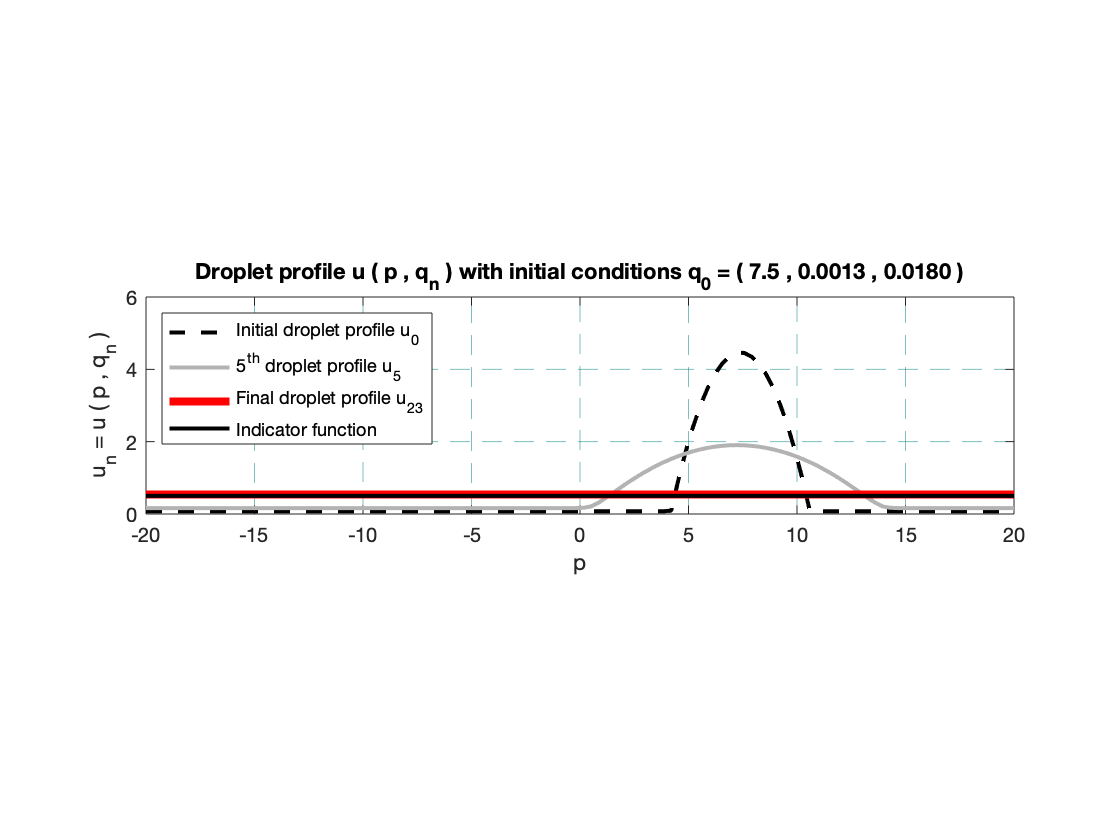


figure;
hold on
plot(X,H_1,'k--','linewidth',2);
plot(X,H1,'-','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_Sol_1,'r-','linewidth',4);
plot(X,h_region,'k-','linewidth',2);
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('u_n = u ( p , q_n )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
legend('Initial droplet profile u_0',...
    '5^{th} droplet profile u_{5}',...
    'Final droplet profile u_{23}',...
    'Indicator function',...
    'Location','northwest');
title('Droplet profile u ( p , q_n ) with initial conditions q_0 = ( 7.5 , 0.0013 , 0.0180 )');
hold off

**Joint Figures**

Fig. 1

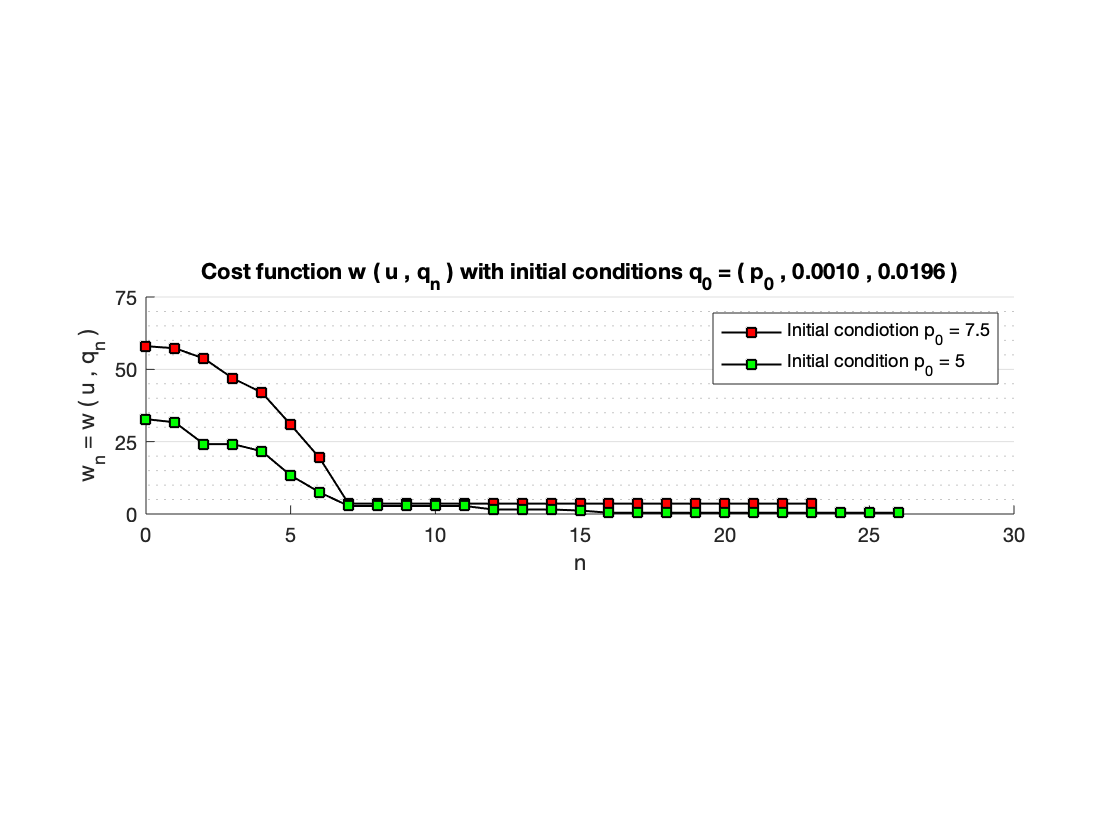

figure;
hold on
plot(0:23,History_1,'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:26,History,'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
ylabel('w_n = w ( u , q_n )');
xlabel('n');
legend('Initial condiotion p_0 = 7.5','Initial condition p_0 = 5','Location','northeast');
title('Cost function w ( u , q_n ) with initial conditions q_0 = ( p_0 , 0.0010 , 0.0196 )');
xlim([0 30]);
ylim([0 75]);
set(gca,'xtick',0:5:100);
set(gca,'ytick',0:25:500);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
pbaspect([4 1 1]);
box off
hold off

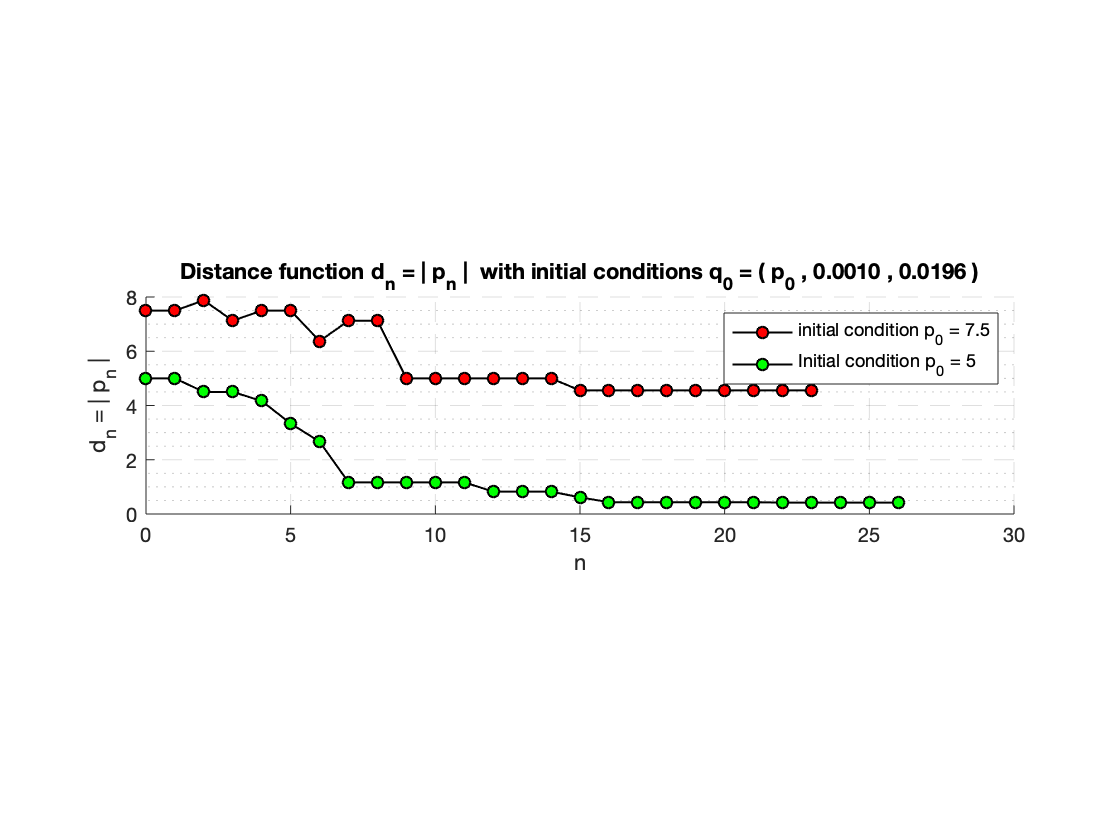


figure;
hold on
plot(0:23,abs(history_1(1,:)),'k-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:26,abs(history(1,:)),'k-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
ylabel('d_n = | p_n |');
xlabel('n');
legend('initial condition p_0 = 7.5','Initial condition p_0 = 5','Location','northeast');
title('Distance function d_n = | p_n |  with initial conditions q_0 = ( p_0 , 0.0010 , 0.0196 )');
xlim([0 30]);
ax = gca;
ax.GridLineStyle = '--';
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
ax.XAxisLocation = 'origin';
pbaspect([4 1 1]);
box off
hold off

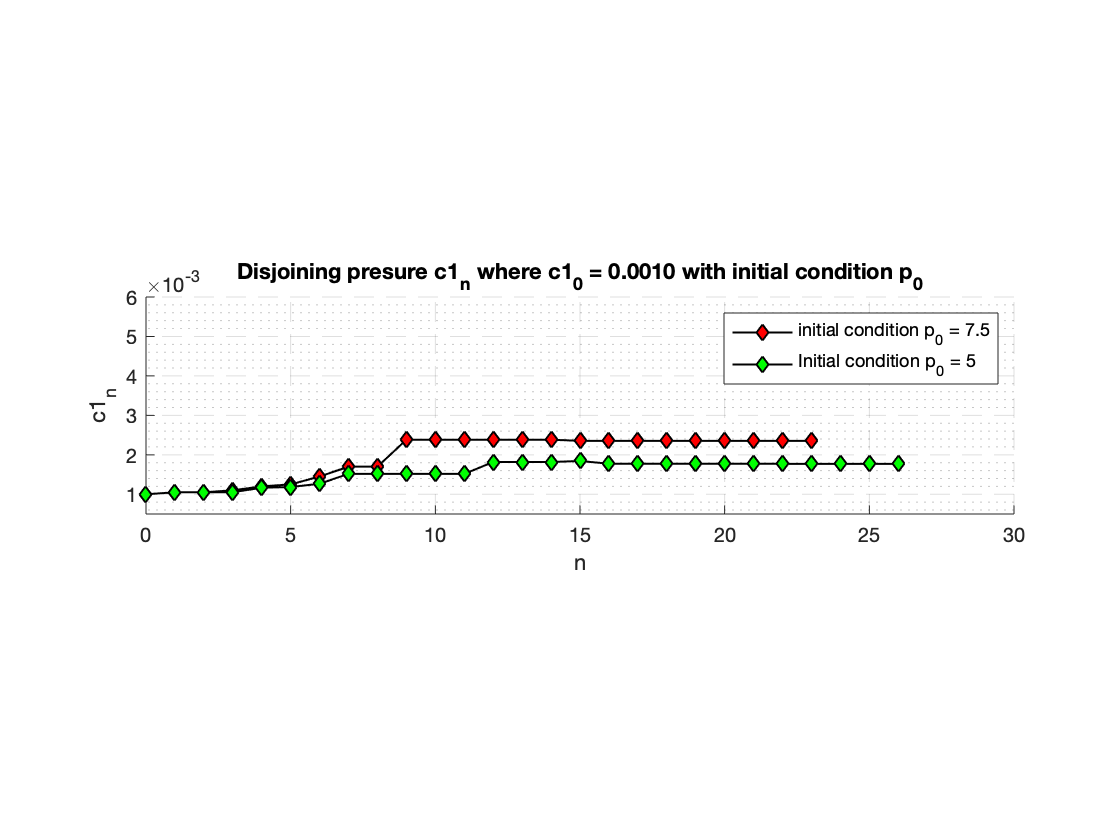



figure;
hold on
plot(0:23,history_1(2,:),'k-d',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:26,history(2,:),'k-d',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
pbaspect([4 1 1]);
ylabel('c1_n');
xlabel('n');
title('Disjoining presure c1_n where c1_0 = 0.0010 with initial condition p_0');
legend('initial condition p_0 = 7.5','Initial condition p_0 = 5','Location','northeast');
xlim([0 30]);
ylim([0.0005 .0060]);
ax = gca;
ax.GridLineStyle = '--';
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
hold off

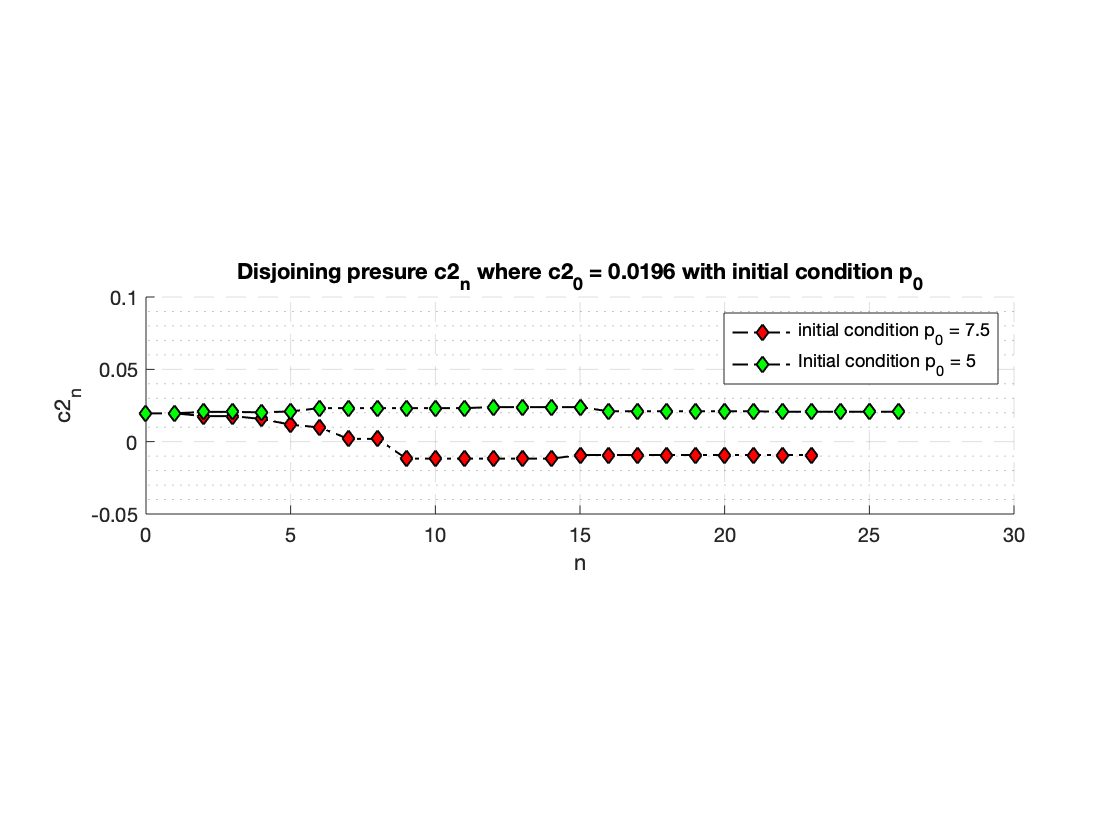



figure;
hold on
plot(0:23,history_1(3,:),'k-.d',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:26,history(3,:),'k-.d',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
pbaspect([4 1 1]);
ylabel('c2_n');
xlabel('n');
title('Disjoining presure c2_n where c2_0 = 0.0196 with initial condition p_0');
legend('initial condition p_0 = 7.5','Initial condition p_0 = 5','Location','northeast');
set(gca,'xtick',0:5:100);
xlim([0 30]);
ylim([-.05 .10]);
ax = gca;
ax.GridLineStyle = '--';
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
hold off